Practica 6: Training

clc;
clear;
inputFolder = 'training/todos';

ads = audioDatastore(inputFolder, 'IncludeSubfolders', false, 'FileExtensions', '.wav');

classes = [];
fileNames = {};

% Leer los archivos y asignar las clases
while hasdata(ads)
    [audioData, dsInfo] = read(ads);

    % Extraer clase del nombre del archivo
    [~, fileName, ~] = fileparts(dsInfo.FileName);
    splitName = split(fileName, '_');
    classLabel = str2double(splitName{1});
    
    % Guardar la clase y el nombre
    classes = [classes; classLabel];
    fileNames{end+1} = dsInfo.FileName;
    
    fprintf('Archivo: %s, Clase: %d, Duración: %.2f segundos\n', ...
        fileName, classLabel, numel(audioData) / dsInfo.SampleRate);
end

Archivo: 10_Diego, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Miguel, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Nancy, Clase: 10, Duración: 1.00 segundos
Archivo: 10_Valeria, Clase: 10, Duración: 1.00 segundos
Archivo: 1_Diego, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Miguel, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Nancy, Clase: 1, Duración: 1.00 segundos
Archivo: 1_Valeria, Clase: 1, Duración: 1.00 segundos
Archivo: 2_Diego, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Miguel, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Nancy, Clase: 2, Duración: 1.00 segundos
Archivo: 2_Valeria, Clase: 2, Duración: 1.00 segundos
Archivo: 3_Diego, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Miguel, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Nancy, Clase: 3, Duración: 1.00 segundos
Archivo: 3_Valeria, Clase: 3, Duración: 1.00 segundos
Archivo: 4_Diego, Clase: 4, Duración: 1.00 segundos
Archivo: 4_Miguel, Clase: 4, Duración: 1.00 segundos
Archivo: 4_Nancy, Clase: 4, Duración: 1.00 

fprintf('Se procesaron %d archivos.\n', numel(fileNames));

Se procesaron 40 archivos.


fs = dsInfo.SampleRate;
windowLength = round(0.03 * fs); % Ventana de 30 ms
overlapLength = round(0.025 * fs); % Solapamiento de 25 ms

afe = audioFeatureExtractor( ...
    SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"), ...
    OverlapLength=overlapLength, ...
    zerocrossrate=true, ...
    shortTimeEnergy=true, ...
    pitch=true, ...
    mfcc=true);

featureMap = info(afe);

features = [];
labels = [];
energyThreshold = 0.005; % Umbral para energía
zcrThreshold = 0.2; % Umbral para tasa de cruces por cero

% Reiniciar el puntero del datastore
reset(ads);

% Extraer características y filtrar
while hasdata(ads)
    [audioData, dsInfo] = read(ads);

    % Extraer características del audio
    thisFeature = extract(afe, audioData);
    isSpeech = thisFeature(:, featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:, featureMap.zerocrossrate) < zcrThreshold;

    % Identificar regiones de voz
    voicedSpeech = isSpeech & isVoiced;

    % Filtrar características no deseadas
    thisFeature(~voicedSpeech, :) = [];
    thisFeature(:, [featureMap.zerocrossrate, featureMap.shortTimeEnergy]) = [];

    % Obtener la etiqueta correspondiente al archivo
    [~, fileName, ~] = fileparts(dsInfo.FileName);
    splitName = split(fileName, '_');
    classLabel = str2double(splitName{1});

    % Asignar etiquetas
    label = repelem(classLabel, size(thisFeature, 1))';
    
    % Guardar características y etiquetas
    features = [features; thisFeature];
    labels = [labels; label];
end

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

fprintf('Extraccion terminada\n');

Extraccion terminada


as

% Configuración inicial
k = 5; % Número de pliegues para validación cruzada
group = labels;
c = cvpartition(group, 'KFold', k); % Validación cruzada estratificada

% Rango de valores para NumNeighbors
neighborRange = 1:10; % Puedes ajustar este rango
accuracies = zeros(size(neighborRange)); % Para almacenar precisiones

for n = neighborRange
    % Entrenar el modelo KNN con NumNeighbors variable
    trainedClassifier = fitcknn(features, labels, ...
        'Distance', "euclidean", ...
        'NumNeighbors', n, ...
        'DistanceWeight', "squaredinverse", ...
        'Standardize', false, ...
        'ClassNames', unique(labels));
    
    % Validación cruzada
    partitionedModel = crossval(trainedClassifier, 'CVPartition', c);
    validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', "ClassifError");
    
    % Almacenar la precisión
    accuracies(n) = validationAccuracy;
    
    fprintf('NumNeighbors = %d, Validation Accuracy = %.2f%%\n', n, validationAccuracy * 100);
end

NumNeighbors = 1, Validation Accuracy = 88.93%
NumNeighbors = 2, Validation Accuracy = 88.91%
NumNeighbors = 3, Validation Accuracy = 87.53%
NumNeighbors = 4, Validation Accuracy = 86.93%
NumNeighbors = 5, Validation Accuracy = 86.36%
NumNeighbors = 6, Validation Accuracy = 85.79%
NumNeighbors = 7, Validation Accuracy = 85.58%
NumNeighbors = 8, Validation Accuracy = 85.04%
NumNeighbors = 9, Validation Accuracy = 84.80%
NumNeighbors = 10, Validation Accuracy = 84.67%



% Determinar el mejor número de vecinos
[bestAccuracy, bestN] = max(accuracies);

% Mostrar resultados finales
fprintf('\nEl mejor NumNeighbors es %d con una precisión de validación de %.2f%%\n', ...
    bestN, bestAccuracy * 100);


El mejor NumNeighbors es 1 con una precisión de validación de 88.93%


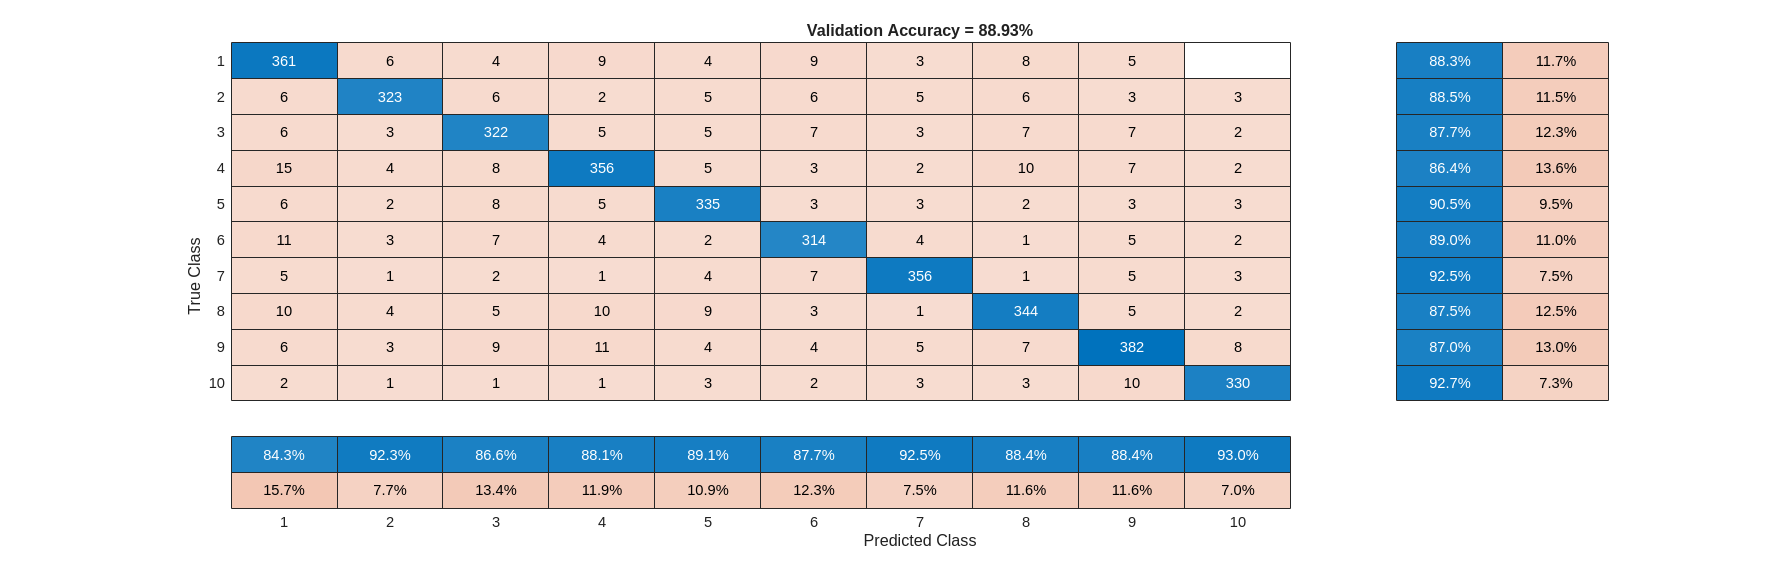


% Entrenar el modelo final con el mejor NumNeighbors
finalClassifier = fitcknn(features, labels, ...
    'Distance', "euclidean", ...
    'NumNeighbors', bestN, ...
    'DistanceWeight', "squaredinverse", ...
    'Standardize', false, ...
    'ClassNames', unique(labels));

% Validación cruzada para el mejor modelo
partitionedModel = crossval(finalClassifier, 'CVPartition', c);
validationPredictions = kfoldPredict(partitionedModel);

% Mostrar la matriz de confusión
figure('Units', "normalized", 'Position', [0.4, 0.4, 0.4, 0.4]);
confusionchart(labels, validationPredictions, ...
    'Title', sprintf("Validation Accuracy = %.2f%%", bestAccuracy * 100), ...
    'ColumnSummary', "column-normalized", ...
    'RowSummary', "row-normalized");

save('knnModel.mat', 'trainedClassifier');
disp('Modelo guardado');

Modelo guardado
